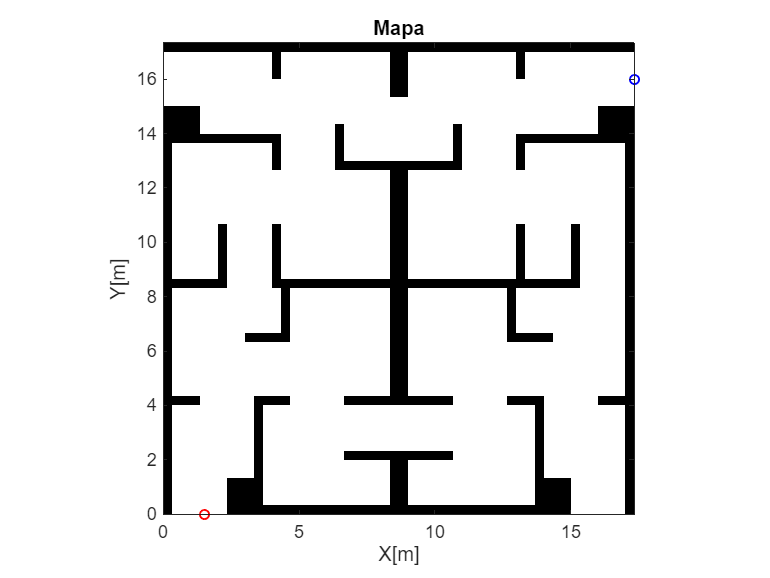

load Celdas_binarias_ejercicio.mat
mapa = binaryOccupancyMap(sm4b,3); %Crear mapa
show(mapa)
hold on
%Punto incial
x1 = 1.5; 
y1 = 0;
start = [x1,y1,pi/2];

%Punto final
x2 = 17.33;
y2 = 16;
goal = [x2,y2,0];
plot(x1,y1,'ro',LineWidth=1,MarkerSize=5)
plot(x2,y2,'bo',LineWidth=1,MarkerSize=5)
xlabel('X[m]')
ylabel('Y[m]')
title('Mapa')
hold off

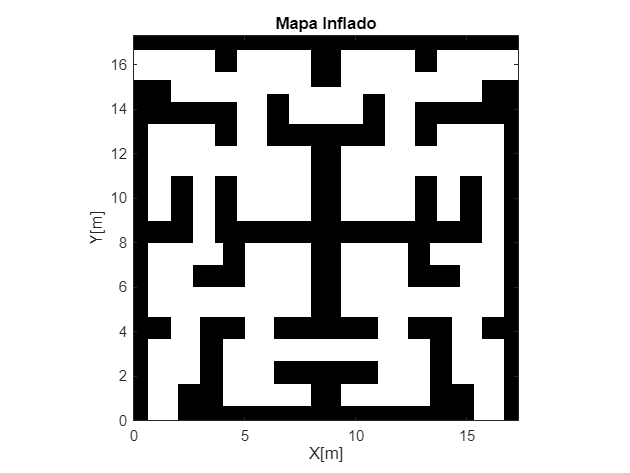

mapaInflado = copy(mapa); %Copia para mapa inflado
r = 0.25; %Valor de inflado
inflate(mapaInflado,r) %Crear mapa inflado
show(mapaInflado)
xlabel('X[m]')
ylabel('Y[m]')
title('Mapa Inflado')

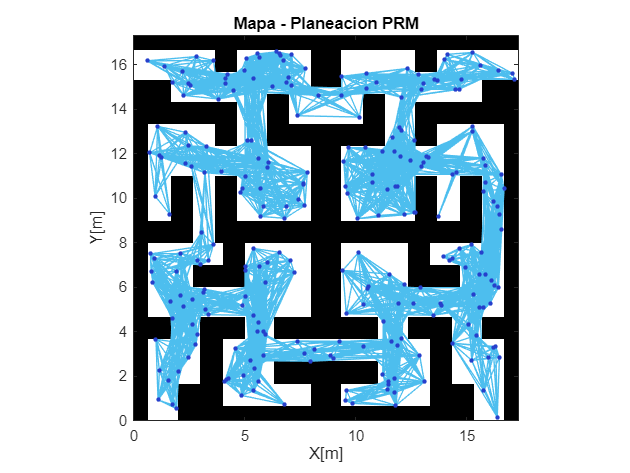

mapPRM = mobileRobotPRM; %Crear objeto para Planificacion PRM
mapPRM.Map = mapaInflado; %Asignacion de mapa
mapPRM.NumNodes = 250; %Cantidad de nodos totales
mapPRM.ConnectionDistance = 5; %Distancia de conexión entre nodos

mapPRM.show
xlabel('X[m]')
ylabel('Y[m]')
title('Mapa - Planeacion PRM')

% Planear la ruta
path = findpath(mapPRM, start(:,1:2), goal(:,1:2)); %Encontrar ruta optima
rutaTabla = array2table(path, 'VariableNames', {'X', 'Y'}); %Convertir ruta a tabla
disp(rutaTabla);

      X          Y   
    ______    _______

       1.5          0
    1.9332    0.54393
    2.0276     2.1989
    2.1132      5.636
     3.051      8.468
    3.2082     11.151
    5.1399     12.597
    5.4115     15.363
    6.2514     15.041
    10.489     14.926
    13.062      15.17
    17.066     15.609
     17.33         16



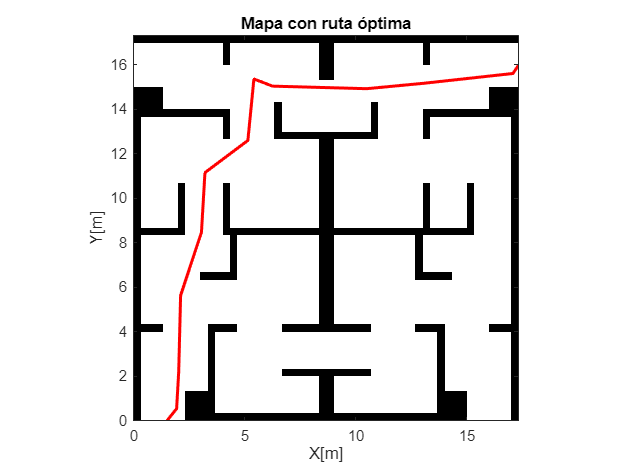

% Mostrar ruta
figure;
show(mapa);  % Mapa sin inflar
hold on;
plot(path(:,1), path(:,2), 'r-', 'LineWidth', 2); % Ruta en rojo
title('Mapa con ruta óptima');
xlabel('X[m]')
ylabel('Y[m]')

% Funcion de costo para PRM
distanciaTotal = sum(sqrt(sum(diff(path).^2, 2)));

fprintf('Función de costo: Distancia total euclidiana\n');

Función de costo: Distancia total euclidiana


fprintf('Valor: %.2f unidades\n', distanciaTotal);

Valor: 28.88 unidades


**Algoritmo RRT**

bounds = [mapa.XWorldLimits; mapa.YWorldLimits; [-pi pi]];
ss = stateSpaceDubins(bounds);
ss.MinTurningRadius = 0.5;

stateValidator = validatorOccupancyMap(ss); 
stateValidator.Map = mapaInflado;
stateValidator.ValidationDistance = 0.4;

planner = plannerRRT(ss,stateValidator);
planner.MaxConnectionDistance = 1;
planner.MaxIterations = 2000;
planner.GoalReachedFcn = @exampleHelperCheckIfGoal;

function isReached = exampleHelperCheckIfGoal(planner, goalState, newState)
    isReached = false;
    threshold = 0.1;
    if planner.StateSpace.distance(newState, goalState) < threshold
        isReached = true;
    end
end

rng default
[pthObj, solnInfo] = plan(planner,start,goal);

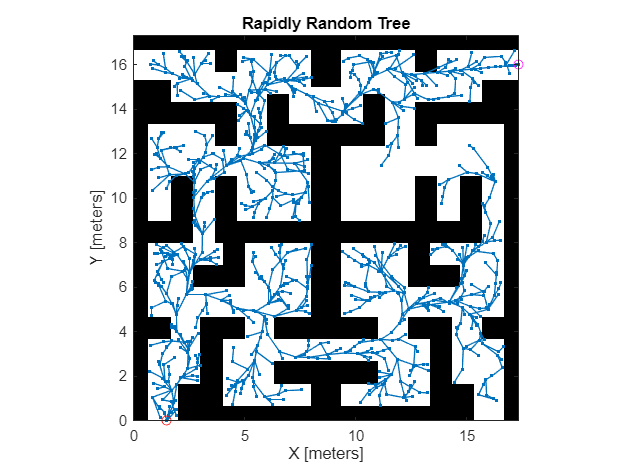

show(mapaInflado)
hold on

% Plot entire search tree.
plot(solnInfo.TreeData(:,1),solnInfo.TreeData(:,2),'.-');

% Interpolate the path.
interpolate(pthObj, 300)

% Show start and goal in grid map.
plot(start(1),start(2),'ro')
plot(goal(1),goal(2),'mo')
title('Rapidly Random Tree');
hold off

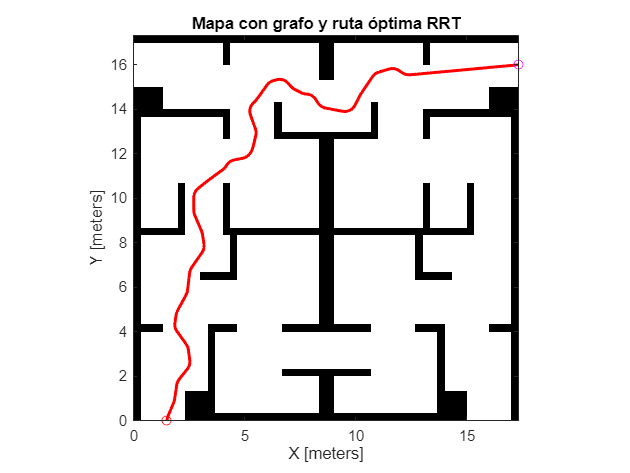

show(mapa)
hold on

% plot path.
plot(pthObj.States(:,1),pthObj.States(:,2),'r-','LineWidth',2)
TablaRRT = array2table(pthObj.States(:,[1,2]),"VariableNames",["x" "y"]);
% Show start and goal in grid map.
plot(start(1),start(2),'ro')
plot(goal(1),goal(2),'mo')
title('Mapa con grafo y ruta óptima RRT');

hold off

% Funcion de costo para RRT
fprintf('Función de costo: Distancia total euclidiana\n');

Función de costo: Distancia total euclidiana


dis_Tot_RRT = table2array(sum(sqrt(sum(diff(TablaRRT).^2, 2))));

fprintf('Valor: %.2f metros\n', dis_Tot_RRT);

Valor: 30.53 metros
